c = 5e3; k = 5e4;  m = 1e3; Yo = 0.01; w = 100;
syms y(t)
[V] = odeToVectorField(m * diff(y, 2) + c * diff(y) + k * y == Yo * (c*w*cos(w*t) + k*sin(w*t)))

$$V = \left(\begin{array}{c} Y_{2}\\ 5\,\cos\left(100\,t\right)+\frac{\sin\left(100\,t\right)}{2}-50\,Y_{1}-5\,Y_{2} \end{array}\right)$$

M = matlabFunction(V, 'vars', {'t', 'Y'})

M = function_handle with value:
    @(t,Y)[Y(2);cos(t.*1.0e2).*5.0+sin(t.*1.0e2).*(1.0./2.0)-Y(1).*5.0e1-Y(2).*5.0]



sol = ode45(M, [0 20], [2 0])

sol = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [1×1202 double]
          y: [2×1202 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


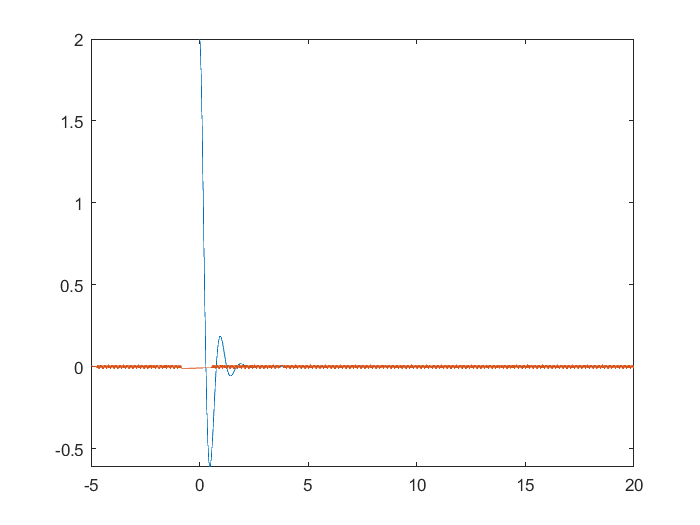

fplot(@(x)deval(sol, x ,1), [0, 20])
    hold on
    
fplot(@(x) Yo * sin(w * x))